Homework #04

## 1

1a)

[1a C21 hand pic]

Represents the covariance between product 2 price and product 1 price

F=[ -6, 47, -42, -66, 35, 21, 9, 2;
89, -64, 4, 56, 20, 11, -59, -57];

[M, N] = size(F);
disp('Covariance Matrix:')

Covariance Matrix:


C=(1/8).*F * F.'

C = 	1.0e+03 *

    1.2645   -0.8900
   -0.8900    2.8025


[U, lambda]=eig(C);
disp('Principal Components:')

Principal Components:


for i = 1:1:length(U)
    disp(U(:, i))
end

   -0.9093
   -0.4161

   -0.4161
    0.9093



[1a T14 hand pic]

Represents the projection of F data at time 4 onto the first PC (the amplitude of 1st PC in the data at time=4)

disp('Expansion Matrix:')

Expansion Matrix:


T=U.' * F

T =   -31.5728  -16.1115   36.5280   36.7173  -40.1480  -23.6727   16.3632   21.8964
   83.4276  -77.7523   21.1117   78.3826    3.6249    1.2656  -57.3955  -52.6645


for i = 1:1:length(U)
    disp('For PC:')
    disp(U(:, i))
    disp(['variance explained = ' num2str(100*lambda(i,i)/sum(lambda(:))) '%'])
end

For PC:


   -0.9093
   -0.4161



variance explained = 21.0793%


For PC:


   -0.4161
    0.9093



variance explained = 78.9207%


1b) So the PC with the greatest eigenvalue, and therefore greatest variance explained, is:

disp('First PC:')

First PC:


disp(U(:,2))

   -0.4161
    0.9093



So this PC tells us that the two product price deviations are inversely correlated such that the first product price tends to be half as deviated and in the opposite direction as the second product price deviation.

So likely these are two products who are related in such a way that their prices are inversely correlated with each other.

1c) "Variance explained by each PCA mode" means how much of the variation in the F dataset can be attributed to each of the principal components (modes).

1d) So each row in F is a variable and therefore the variance for each row/variable m of F is:


$$\frac{1}{N} \sum_{n=1}^{N}(f_{mn})^2$$


Total variance is the sum of these for every row:


$$\sum_{m=1}^{M}(\frac{1}{N}\sum_{n=1}^{N}(f_{mn})^2) = \sum_{m=1}^{M}\sum_{n=1}^{N}\frac{1}{N}(f_{mn})^2$$


which is the trace/sum of eigenvalues of the covariance matrix:


$$=\mathrm{trace}(\frac{1}{N}FF^T)=\mathrm{trace}(C)=\sum_{j=1}^M(\lambda_j)$$


the fraction of explained variance for the ith PC is then:


$$\frac{\lambda_i}{\sum_{j=1}^M(\lambda_j)}$$


## 2

2a)

% Matlab
%
N=1300; t=1:N;
V1=[1;2;0;-1.1;0];
V2=[0;-1;0;-0.8;0];
V3=[1.5;0;0;-0.6;1.5];
F=3*V1*cos(t/5) ...
+2*V2*cos(t/3)...
+1.5*V3*cos(t/7);

[M, N] = size(F)

M = 5

N = 1300

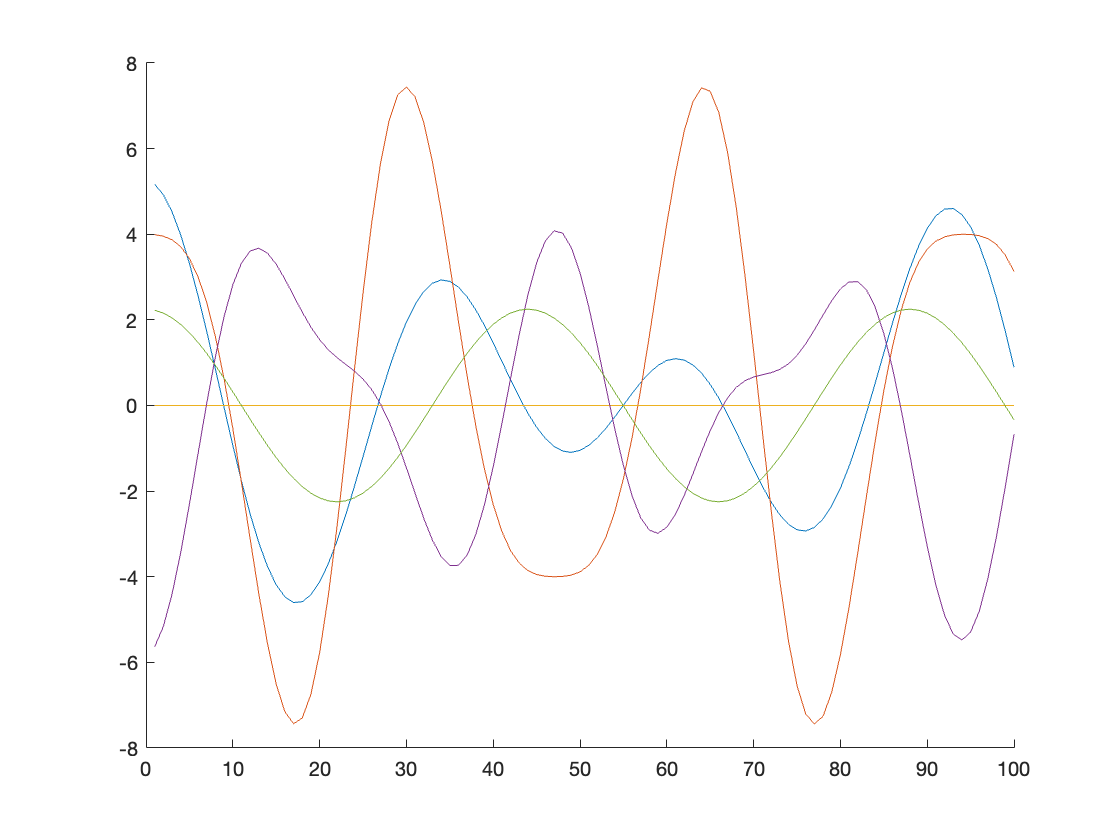

figure; hold on
for i=1:1:M
    plot(t(1, 1:100), F(i, 1:100))
end
hold off

2b)

F_prime = F - mean(F,2);
disp('Covariance Matrix:')

Covariance Matrix:


C=(1/N).*F_prime * F_prime.'

C =     6.9365    8.8994         0   -5.8796    2.4911
    8.8994   19.9962         0   -8.2378   -0.0898
         0         0         0         0         0
   -5.8796   -8.2378         0    7.0627   -0.9661
    2.4911   -0.0898         0   -0.9661    2.5354


Interpretation of covariance matrix: the matrix that contains the covariance of each stock's price with all the other stock prices and itself.

disp('Verifying C is symmetric:')

Verifying C is symmetric:


disp(C*C.')

  168.0892  287.8954         0 -158.0275   28.4769
  287.8954  546.9162         0 -275.1428   28.1051
         0         0         0         0         0
 -158.0275 -275.1428         0  153.2455  -23.1802
   28.4769   28.1051         0  -23.1802   13.5753



disp(C.'*C)

  168.0892  287.8954         0 -158.0275   28.4769
  287.8954  546.9162         0 -275.1428   28.1051
         0         0         0         0         0
 -158.0275 -275.1428         0  153.2455  -23.1802
   28.4769   28.1051         0  -23.1802   13.5753



$CC^T=C^TC$ so C is indeed symmetric.

The diagonal entries contain that specific stock price's own variance across the days, where C(i,i) is the variance for stock price i.

Stock 2 has the highest variance, then stock 4, then stock 1, then stock 5, and stock 3 does not vary/has 0 variance.

The non-diagonal entries above the diagonal contain the covariances between stock prices, so C(i,j) is the covariance between stock i price and stock j price.

Stock 1 is positively correlated with stocks 2 and somewhat with 5, and it is negatively correlated with stock 4.

Stock 2 is also negatively correlated with stock 4 and barely negatively correlated with stock 5.

Stock 4 is slightly negatively correlated with stock 5.

Stock 3 is not correlated with any of them.

2c)

[U, lambda]=eig(C);
disp('Principal Components:')

Principal Components:


for i = 1:1:length(U)
    disp(U(:, i))
    disp(['with eigenvalue: ' num2str(lambda(i,i))])
end

   -0.4353
   -0.7969
         0
    0.4155
   -0.0531



with eigenvalue: 29.1461


   -0.4977
    0.5057
         0
    0.3721
   -0.5984



with eigenvalue: 5.284


   -0.7160
    0.2121
         0
   -0.2652
    0.6099



with eigenvalue: -5.0555e-15


    0.2240
    0.2533
         0
    0.7865
    0.5168



with eigenvalue: 2.1008


     0
     0
     1
     0
     0



with eigenvalue: 0


For each PC, stock prices that are more strongly correlated with each other will be of similar sign and larger in magnitude. And then for each PC, the eigenvalue tells us how well it explains the total data variance.

2d)

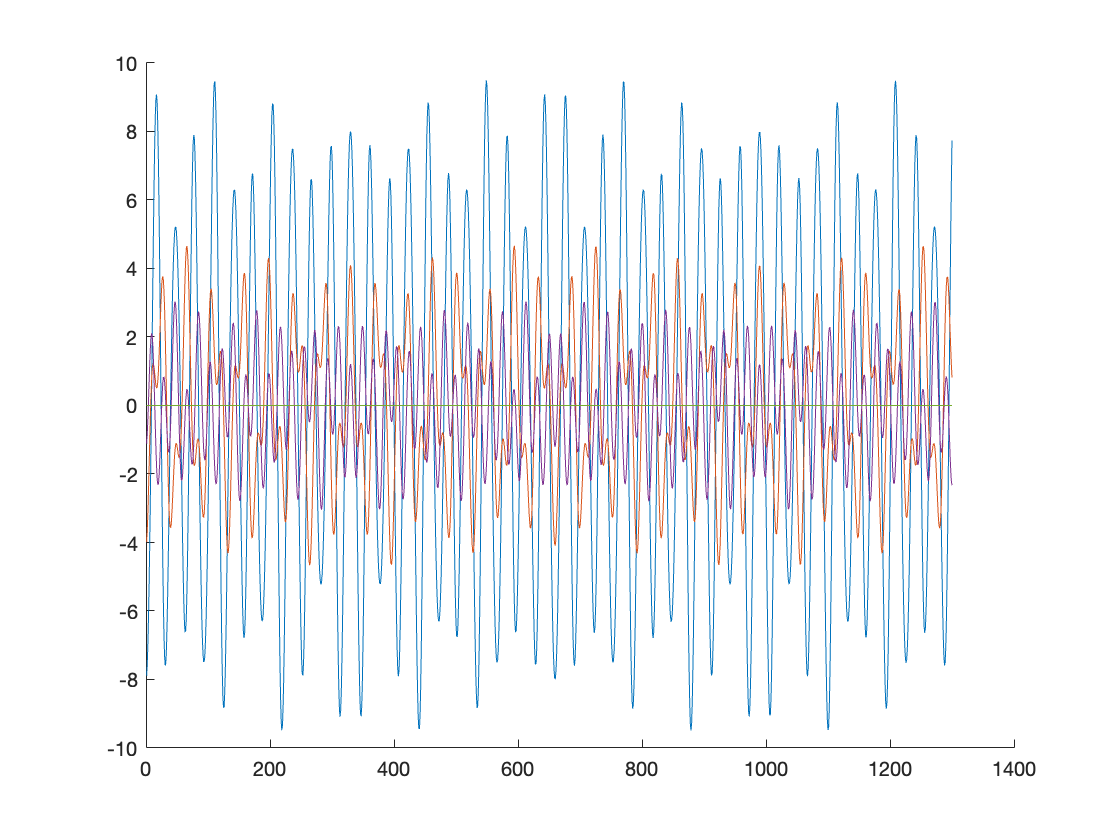

T=U.'*F;

figure; hold on
n_N = N;
n=1:1:n_N;
for i = 1:1:M
    plot(n, T(i, 1:n_N))
end
hold off

2e) 1st, 2nd, 3rd PC has significantly greater eigenvalue than the last two (which are basically 0). So we can use k=3.

reconst_PCs=[1,2,4];

F_reconst=U(:,reconst_PCs)*T(reconst_PCs, :)

F_reconst =     5.1673    4.9220    4.5225    3.9827    3.3209    2.5599    1.7256    0.8461   -0.0488   -0.9295   -1.7669   -2.5339   -3.2062   -3.7630   -4.1881   -4.4699   -4.6023   -4.5844   -4.4206   -4.1205   -3.6983   -3.1720   -2.5631   -1.8955   -1.1943   -0.4855    0.2059    0.8560    1.4433    1.9494    2.3596    2.6634    2.8550    2.9328    2.8999    2.7640    2.5361    2.2309    1.8656    1.4591    1.0314    0.6025    0.1917   -0.1833   -0.5071   -0.7674   -0.9549   -1.0646   -1.0950   -1.0487
    3.9905    3.9546    3.8714    3.7098    3.4333    3.0064    2.4013    1.6035    0.6168   -0.5335   -1.8004   -3.1171   -4.4012   -5.5619   -6.5073   -7.1534   -7.4326   -7.3009   -6.7433   -5.7766   -4.4494   -2.8389   -1.0454    0.8160    2.6244    4.2634    5.6304    6.6450    7.2549    7.4392    7.2090    6.6051    5.6925    4.5536    3.2797    1.9624    0.6853   -0.4824   -1.4912   -2.3130   -2.9416   -3.3892   -3.6825   -3.8564   -3.9474   -3.9878   -3.9999   -3.9928   -3.9

figure; hold on
for i=1:1:M
    plot(t(1, 1:100), F_reconst(i, 1:100))
end
hold off

This reconstruction from 3 PC's has similar values and importantly, similar trends to F:

F

F =     5.1673    4.9220    4.5225    3.9827    3.3209    2.5599    1.7256    0.8461   -0.0488   -0.9295   -1.7669   -2.5339   -3.2062   -3.7630   -4.1881   -4.4699   -4.6023   -4.5844   -4.4206   -4.1205   -3.6983   -3.1720   -2.5631   -1.8955   -1.1943   -0.4855    0.2059    0.8560    1.4433    1.9494    2.3596    2.6634    2.8550    2.9328    2.8999    2.7640    2.5361    2.2309    1.8656    1.4591    1.0314    0.6025    0.1917   -0.1833   -0.5071   -0.7674   -0.9549   -1.0646   -1.0950   -1.0487
    3.9905    3.9546    3.8714    3.7098    3.4333    3.0064    2.4013    1.6035    0.6168   -0.5335   -1.8004   -3.1171   -4.4012   -5.5619   -6.5073   -7.1534   -7.4326   -7.3009   -6.7433   -5.7766   -4.4494   -2.8389   -1.0454    0.8160    2.6244    4.2634    5.6304    6.6450    7.2549    7.4392    7.2090    6.6051    5.6925    4.5536    3.2797    1.9624    0.6853   -0.4824   -1.4912   -2.3130   -2.9416   -3.3892   -3.6825   -3.8564   -3.9474   -3.9878   -3.9999   -3.9928   -3.9611   -3

figure; hold on
for i=1:1:M
    plot(t(1, 1:100), F(i, 1:100))
end
hold off

The data were originally constructed using 3 cosine function signals of varying amplitudes, so it makes sense that it is best reconstructed with 3 PCs.

## 3

3a)

A is 2x3 so A*A^T will have the smaller dimension and therefore will be used for this SVD.

[3a]

A=[-10,-9,8;-0,4,3];

[U,S,V]=svd(A)

U =     0.9985   -0.0543
   -0.0543   -0.9985


S =    15.6733         0         0
         0    4.9343         0


V =    -0.6371    0.1101    0.7629
   -0.5872   -0.7104   -0.3879
    0.4993   -0.6951    0.5172


They are the same

## 4

4a)

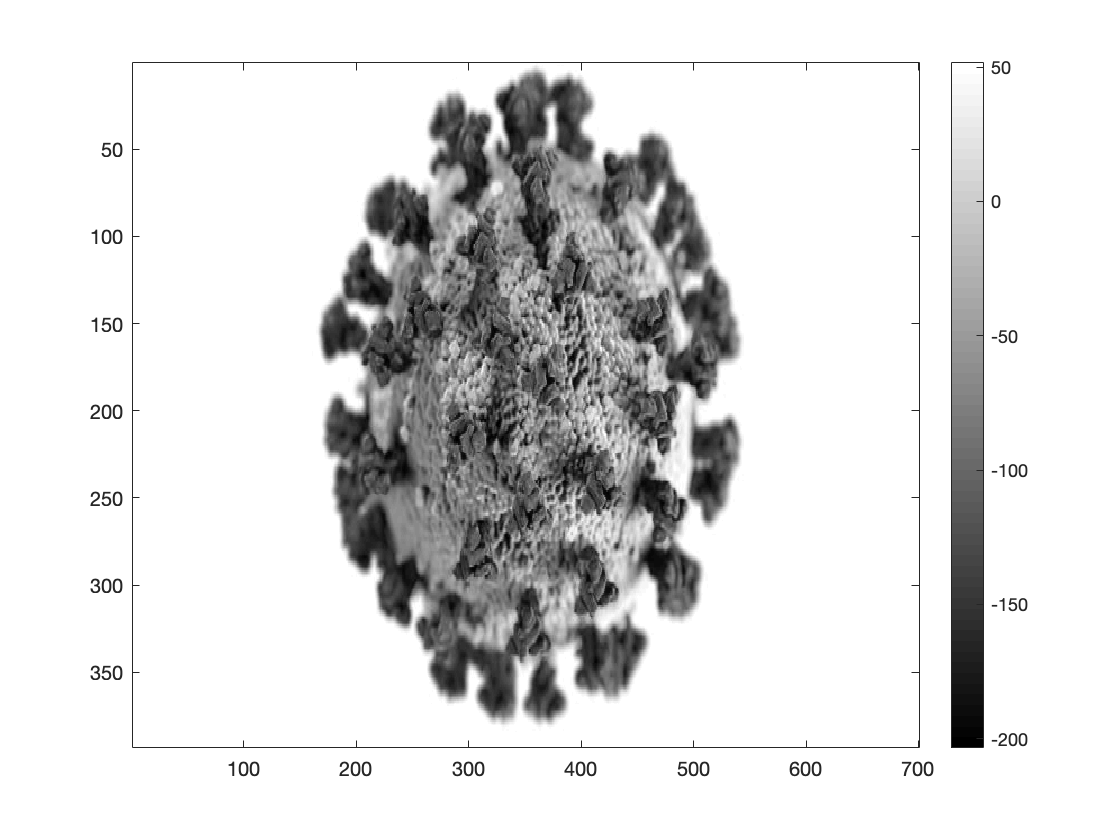

% Matlab
A=double(rgb2gray(imread('./coronavirus.jpg'))); A=A-mean(A(:));
figure(1); clf; imagesc(A); colormap(gray); colorbar

[M, N]=size(A);
[U,S,V]=svd(A)

U =    -0.0063   -0.0625    0.0099   -0.0796    0.0304   -0.0600    0.0484   -0.0215    0.1114   -0.0465    0.0476   -0.0025    0.0158   -0.0263    0.0107   -0.0048    0.0109   -0.0451   -0.0108    0.0206   -0.0045    0.0038   -0.0085    0.0011   -0.0033    0.0026   -0.0013    0.0032   -0.0266    0.0031   -0.0023    0.0038    0.0120   -0.0106   -0.0014    0.0151    0.0078   -0.0062   -0.0113    0.0080    0.0217   -0.0121   -0.0075   -0.0174    0.0053    0.0085   -0.0006   -0.0056   -0.0028   -0.0015
   -0.0062   -0.0627    0.0100   -0.0797    0.0302   -0.0592    0.0485   -0.0208    0.1105   -0.0463    0.0467   -0.0024    0.0162   -0.0251    0.0097   -0.0052    0.0093   -0.0444   -0.0097    0.0198   -0.0021    0.0026   -0.0079    0.0003   -0.0021    0.0014    0.0004    0.0000   -0.0234    0.0011   -0.0015    0.0040    0.0085   -0.0087   -0.0012    0.0131    0.0071   -0.0066   -0.0100    0.0088    0.0225   -0.0059   -0.0068   -0.0161    0.0051    0.0076    0.0005   -0.0025    0.0016   -0

S = 	1.0e+04 *

    3.0118         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    1.4580         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

V =     0.0313   -0.0219    0.0072   -0.0202    0.0102   -0.0118    0.0130   -0.0052    0.0212   -0.0073    0.0059   -0.0014    0.0015   -0.0064   -0.0012   -0.0059    0.0032   -0.0023    0.0004    0.0015    0.0015   -0.0005    0.0001   -0.0001   -0.0001   -0.0015    0.0007    0.0006   -0.0007   -0.0004    0.0003    0.0001   -0.0014    0.0000    0.0005    0.0025   -0.0003   -0.0003    0.0000    0.0019    0.0002    0.0001   -0.0001    0.0006    0.0023   -0.0008   -0.0000   -0.0011    0.0001    0.0001
    0.0313   -0.0219    0.0072   -0.0202    0.0102   -0.0118    0.0130   -0.0052    0.0212   -0.0073    0.0059   -0.0014    0.0015   -0.0064   -0.0012   -0.0059    0.0032   -0.0023    0.0004    0.0015    0.0015   -0.0005    0.0001   -0.0001   -0.0001   -0.0015    0.0007    0.0006   -0.0007   -0.0004    0.0003    0.0001   -0.0014    0.0000    0.0005    0.0025   -0.0003   -0.0003    0.0000    0.0019    0.0002    0.0001   -0.0001    0.0006    0.0023   -0.0008   -0.0000   -0.0011    0.0001    0


m=1:1:M;
s=m;
for i = 1:1:M
    s(i) = S(i,i);
end
figure
disp('non-log plot:')

non-log plot:


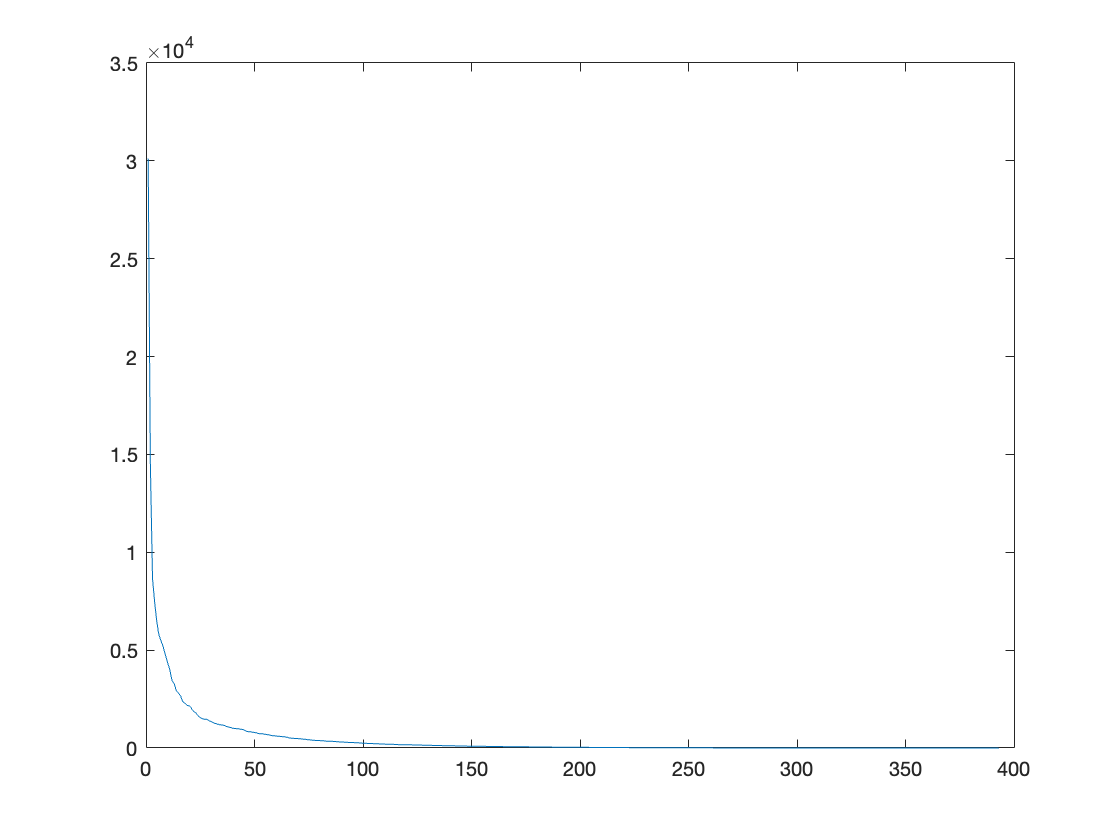

plot(m,s)

figure
disp('log10 plot:')

log10 plot:


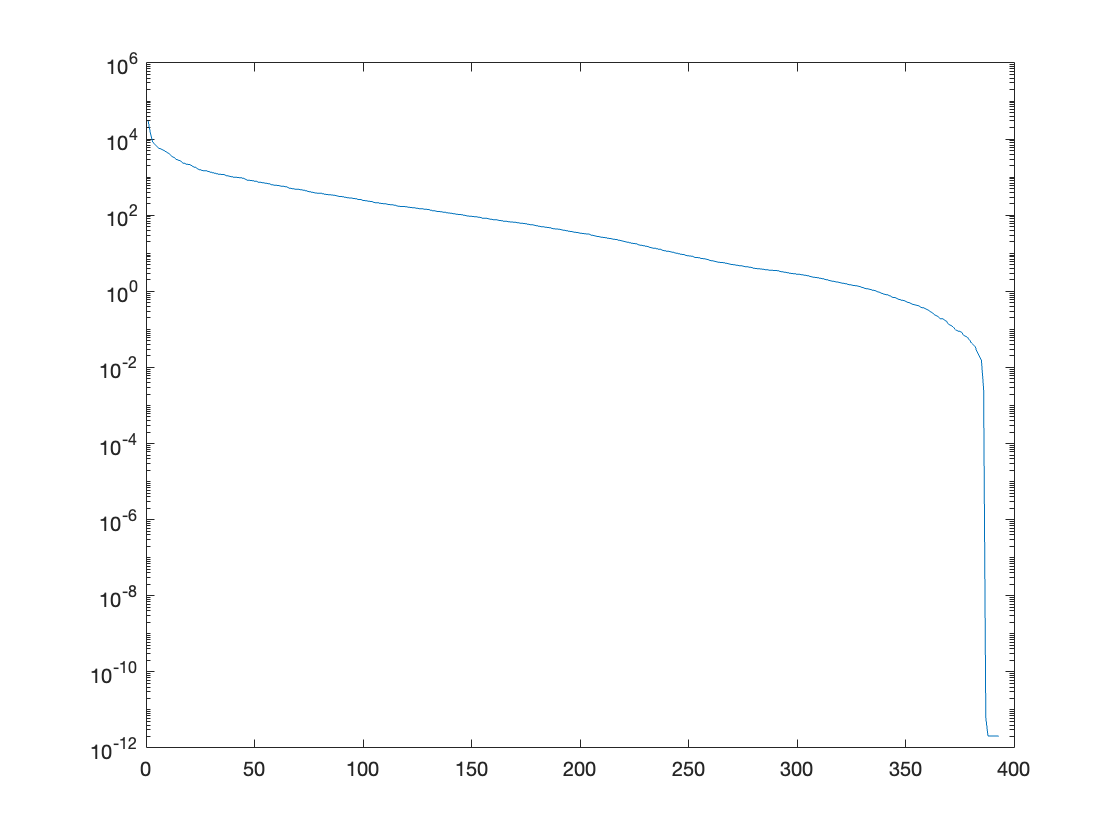

semilogy(m,s)

Looks like singular values get close to 0 after around 25. So I predict 25 modes.

4b)

# of modes: 5


variance explained: 82.5591%


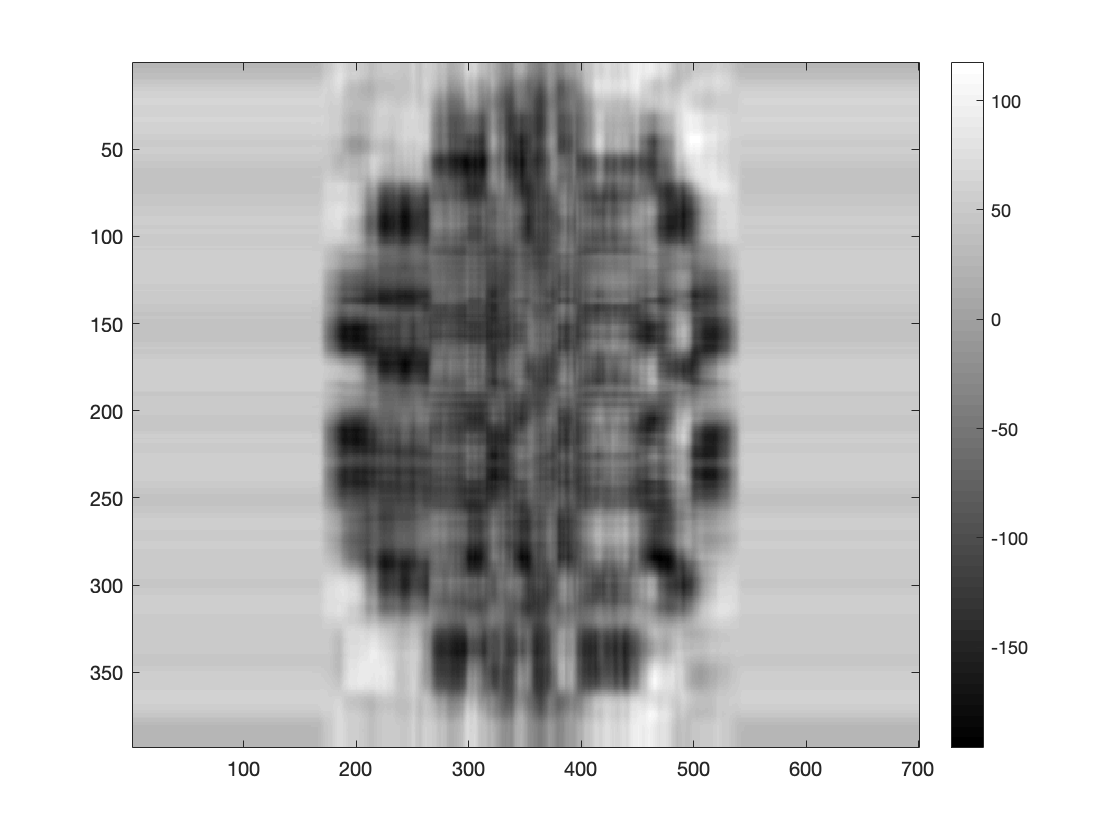

# of modes: 25


variance explained: 97.1502%


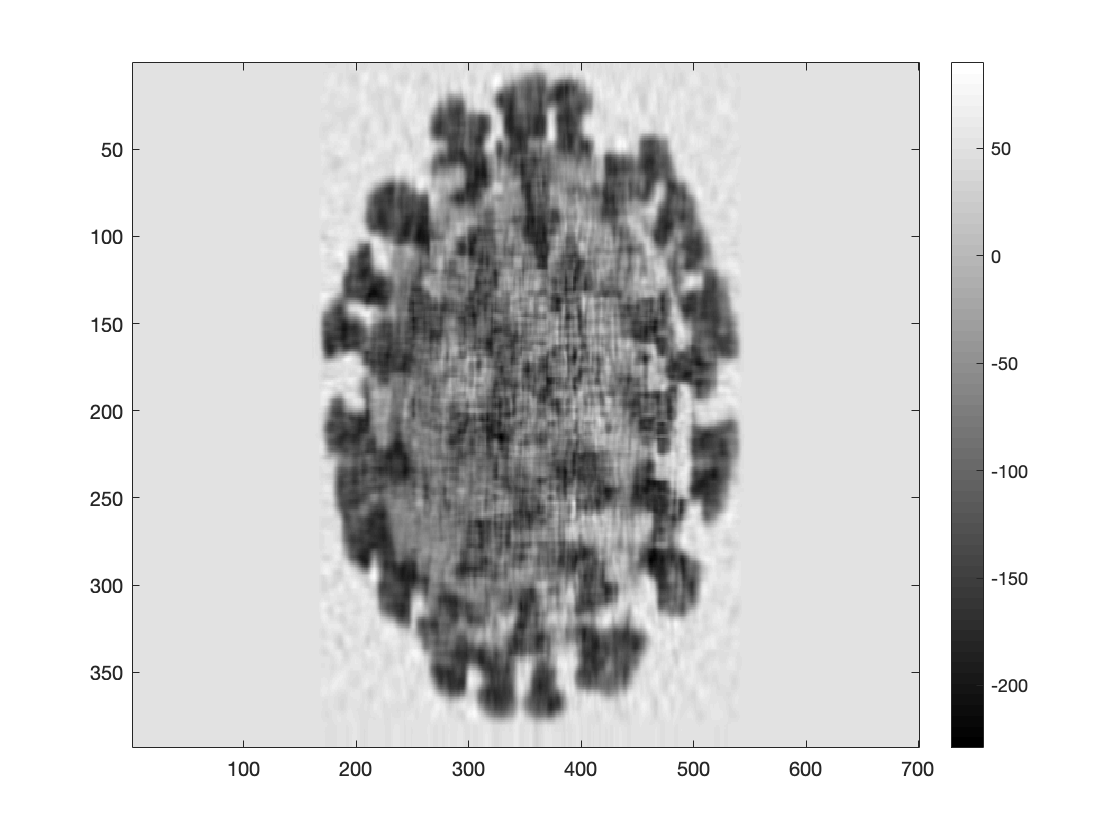

# of modes: 50


variance explained: 99.1807%


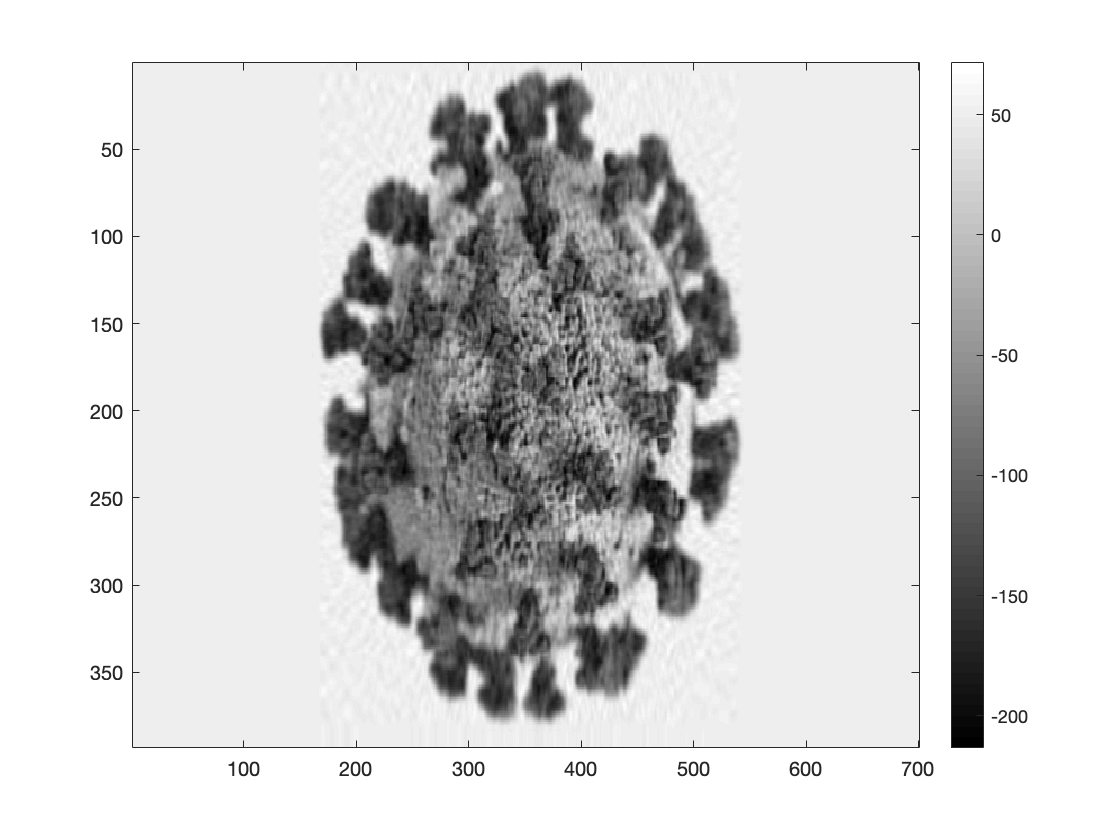

# of modes: 100


variance explained: 99.9035%


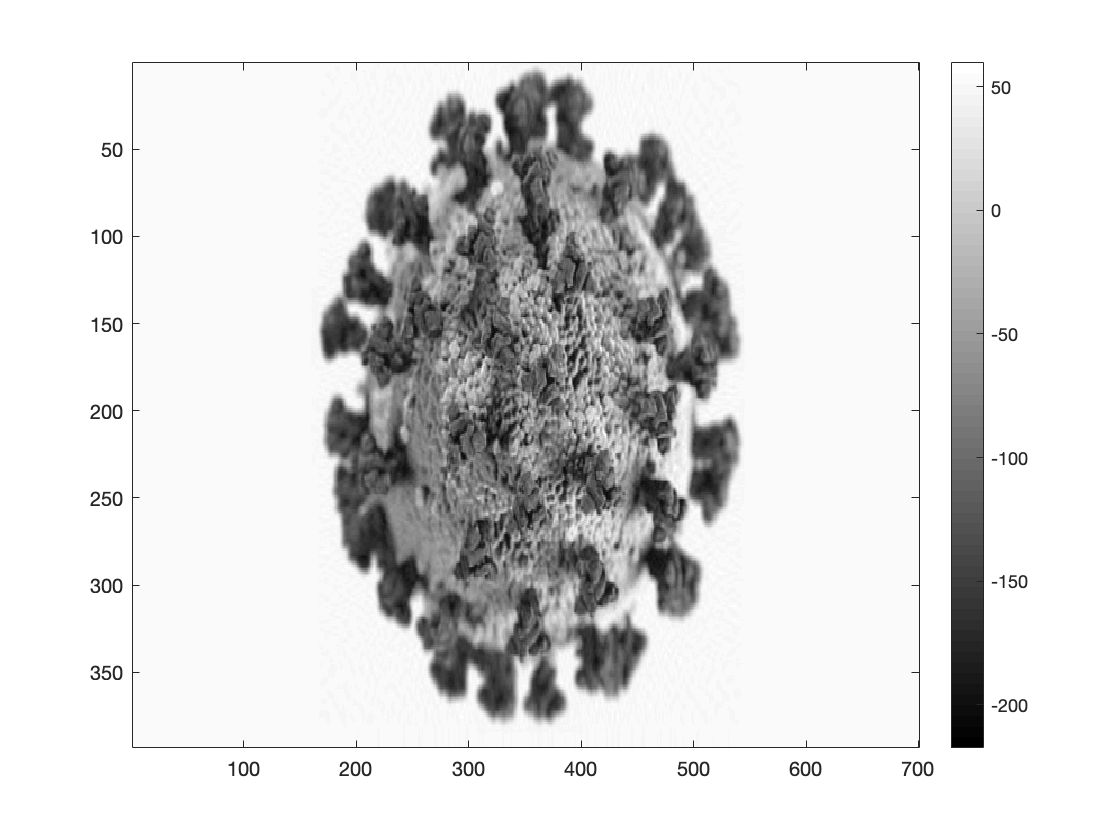

for n_modes = [5, 25, 50, 100]
    S_reconst = S;
    S_reconst(n_modes+1:end, n_modes+1:end) = 0;
    A_reconst = U*S_reconst*V.';
    disp(['# of modes: ' num2str(n_modes)])
    exp_var = 100.*sum(diag(S(1:n_modes,1:n_modes)).^2)/sum(diag(S(:,:)).^2);
    disp(['variance explained: ' num2str(exp_var) '%'])
    figure; imagesc(A_reconst); colormap(gray); colorbar
end

4c) n_modes=25 looks good and its explained variance is pretty close to 100%.

n_modes=25

n_modes = 25

compression_ratio=(n_modes+(n_modes*M)+(n_modes*N))/(M*N);
disp(['storage saved as 1-compression ratio: ' num2str(100- (100*compression_ratio)) '%'])

storage saved as 1-compression ratio: 90.0582%


## 5

5a)

A=[ 1.97, 3.59, -0.177, 0.726;
-4.06, 0.879, -0.513, 3.4;
0.411, 5.16, -0.308, 0.756;
3.34, -2.41, -0.0974, 3.33];
[M, N]=size(A);

disp('From SVD:')

From SVD:


[U,S,V]=svd(A);
svd_norm=S(1,1)

svd_norm = 6.8390

svd_cond=S(1,1)/S(M,M)

svd_cond = 5.1683e+04


disp('From Matlab:')

From Matlab:


norm(A)

ans = 6.8390

cond(A)

ans = 5.1683e+04

Norm and condition from SVD are in fact equal to Matlab's norm() and cond() functions.

5b)

[V,D] = eig(A.'*A)

V =    -0.0337    0.1127    0.9788   -0.1676
    0.0477   -0.0626    0.1768    0.9811
    0.9935   -0.0900    0.0342   -0.0602
    0.0974    0.9876   -0.0974    0.0759


D =     0.0000         0         0         0
         0   23.7682         0         0
         0         0   31.3893         0
         0         0         0   46.7723


max eigenvalue is 4th one

x_for_normA=V(:,4)

x_for_normA =    -0.1676
    0.9811
   -0.0602
    0.0759


5c)

b =[ 0.476; 0.268; 0.741; -0.391];
delta_b=[-0.744; -0.153; 0.626; 0.176];

x=inv(A)*b;
x_error=inv(A)*(b + delta_b)

x_error = 	1.0e+03 *

   -0.2543
    0.3608
    7.5063
    0.7357



disp('relative solution error:')

relative solution error:


disp(norm(x_error - x)/norm(x))

   6.6595e+03



disp('relative error of b:')

relative error of b:


disp(norm(delta_b)/norm(b))

    0.9997



5d)

A1=[ 2.98, 0.383, 2.11, -0.942;
0.938, 2.14, 3.81, -1.98;
-0.649, 0.775, 1.16, -0.416;
1.49, 0.118, 3.61, 0.483];
[M, N]=size(A1);

[U,sigma,V]=svd(A1)

U =    -0.4887    0.5889    0.5416   -0.3479
   -0.6816   -0.5802    0.2520    0.3678
   -0.1495   -0.4523   -0.1939   -0.8576
   -0.5236    0.3347   -0.7782    0.0907


sigma =     6.7873         0         0         0
         0    2.5970         0         0
         0         0    1.8682         0
         0         0         0    0.0000


V =    -0.4094    0.7712    0.4372   -0.2155
   -0.2687   -0.5110    0.2701   -0.7706
   -0.8386   -0.1094   -0.4986    0.1902
    0.2386    0.3634   -0.6981   -0.5689


so Vmax is the 1st and Vmin is the 4th

b1=V(:,1)

b1 =    -0.4094
   -0.2687
   -0.8386
    0.2386


delta_b1=V(:,4)*0.01

delta_b1 =    -0.0022
   -0.0077
    0.0019
   -0.0057


disp(norm(delta_b1))

    0.0100



x1=inv(A1)*b1;
delta_x1=inv(A1)*delta_b1;
disp('max relative solution error:')

max relative solution error:


disp(norm(delta_x1)/norm(x1))

    0.0054



## 6

c=10:1:30;
n=1;
for N=10:1:30
    dx=(1/N);
    gamma=2;
    
    A=zeros([N,N]);
    for i=1:1:N
       A(i, i)=(-2/(dx^2))-gamma;
       if i==1
           A(i, N)=1/(dx^2);
       else
           A(i, i-1)=1/(dx^2);
       end
       if i==N
           A(i, 1)=1/(dx^2);
       else
           A(i, i+1)=1/(dx^2);
       end
    end
    c(n)=norm(inv(A))*norm(A);
    disp(['condition number for N=' num2str(N) ': ' num2str(c(n))])
    n=n+1;
end

condition number for N=10: 201
condition number for N=11: 238.0986
condition number for N=12: 289
condition number for N=13: 334.0892
condition number for N=14: 393
condition number for N=15: 446.0832
condition number for N=16: 513
condition number for N=17: 574.0792
condition number for N=18: 649
condition number for N=19: 718.0764
condition number for N=20: 801
condition number for N=21: 878.0744
condition number for N=22: 969
condition number for N=23: 1054.0729
condition number for N=24: 1153
condition number for N=25: 1246.0717
condition number for N=26: 1353
condition number for N=27: 1454.0708
condition number for N=28: 1569
condition number for N=29: 1678.07
condition number for N=30: 1801


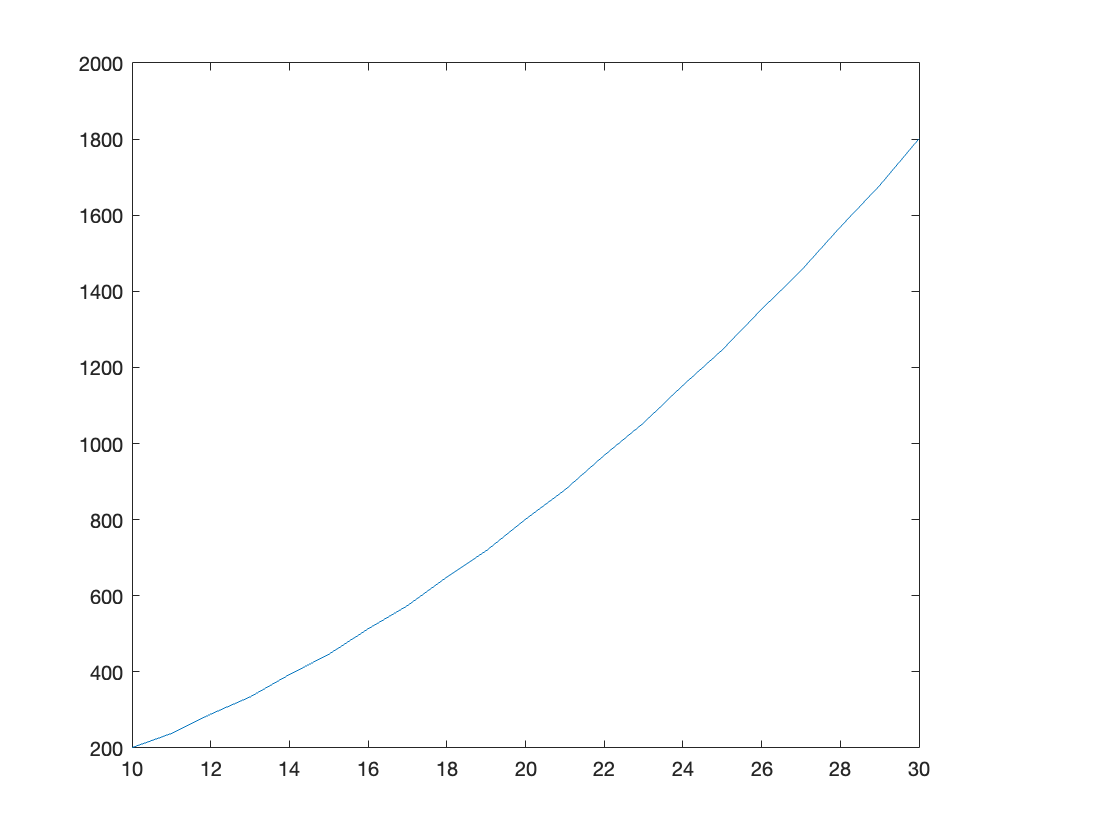


plot(10:1:30, c)

But from OH, TF said to insert gamma within the parentheses:

c=10:1:30;
n=1;
for N=10:1:30
    dx=(1/N);
    gamma=2;
    
    A=zeros([N,N]);
    for i=1:1:N
       A(i, i)=((-2-gamma)/(dx^2));
       if i==1
           A(i, N)=1/(dx^2);
       else
           A(i, i-1)=1/(dx^2);
       end
       if i==N
           A(i, 1)=1/(dx^2);
       else
           A(i, i+1)=1/(dx^2);
       end
    end
    c(n)=norm(inv(A))*norm(A);
    disp(['condition number for N=' num2str(N) ': ' num2str(c(n))])
    n=n+1;
end

condition number for N=10: 3
condition number for N=11: 2.9595
condition number for N=12: 3
condition number for N=13: 2.9709
condition number for N=14: 3
condition number for N=15: 2.9781
condition number for N=16: 3
condition number for N=17: 2.983
condition number for N=18: 3
condition number for N=19: 2.9864
condition number for N=20: 3
condition number for N=21: 2.9888
condition number for N=22: 3
condition number for N=23: 2.9907
condition number for N=24: 3
condition number for N=25: 2.9921
condition number for N=26: 3
condition number for N=27: 2.9932
condition number for N=28: 3
condition number for N=29: 2.9941
condition number for N=30: 3


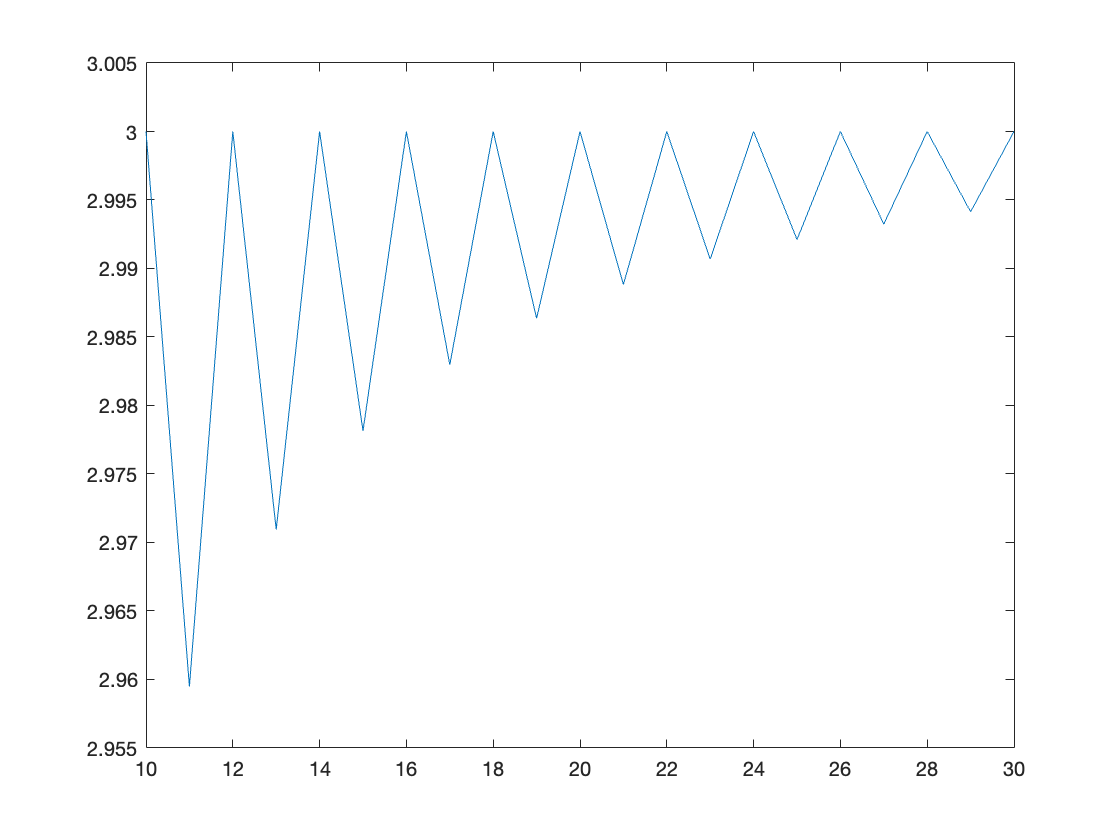


plot(10:1:30, c)